# **Tips for Training Neural Networks**

## 1. Data Preprocessing

Neural networks tend to learn best when all inputs and outputs have similar magnitudes. 

If your data does not satisfy this condition, it may be necessary to rescale or offset certain features in the dataset. 

For example, let's consider the task of approximating the following function: 

                                $f\left(x_1 ,x_2 \right)=x_1^2 +{0\ldotp 01x}_2^2$ , $x_1 \in \left\lbrack -2,2\right\rbrack ,x_{2\;} \in \left\lbrack -100,100\right\rbrack$

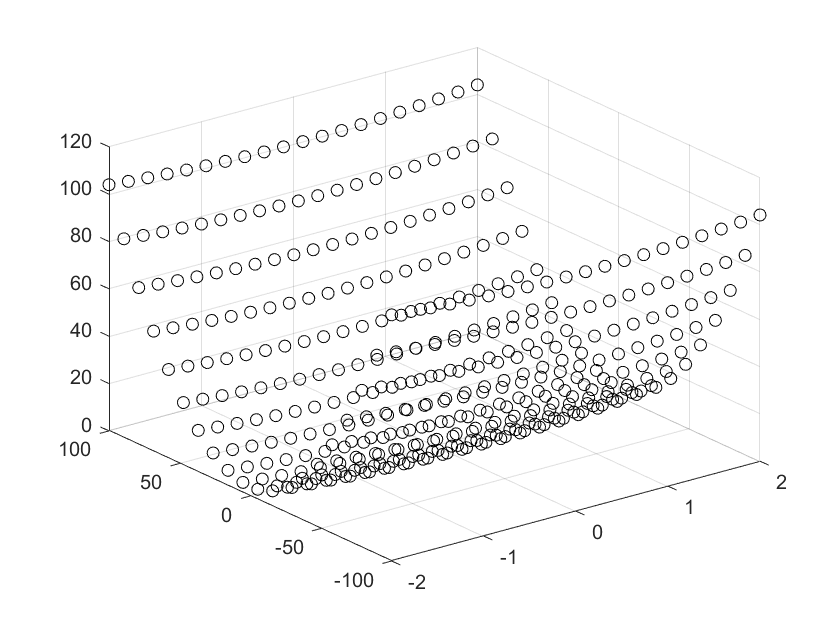

% Generate Data and Labels for Fitting
clear; clc; close all
n=20;
x1=linspace(-2,2,n);
x2=linspace(-100,100,n);
counter=0;
for i=1:n
    for j=1:n
        counter=counter+1;
        data(1,counter)=x1(i);
        data(2,counter)=x2(j);
        label(counter)=x1(i)^2+0.01*x2(j)^2;
    end
end
% Visualize Data
scatter3(data(1,:),data(2,:),label,'black')

This dataset does not satisfy the aforementioned condition. If you try to fit the surface directly, 

you will find that it is challenging for neural networks to approximate it. 

This is because the minimization problem posed by this dataset is difficult to solve. 

Therefore, **it is crucial for users to perform data preprocessing before optimization.**

If you are not familiar with preprocessing methods, the package provides a fundamental technique: normalization.

                                                       
$$\hat{x_1 } =\frac{x_1 -\mu_1 }{\sigma_1 },\hat{x_2 } =\frac{x_2 -\mu_2 }{\sigma_2 }$$


where $\mu {\;}_1 ,\mu_{2\;} ,\sigma {\;}_1 ,\sigma {\;}_2$ are mean and standard deviation of $x_1$ and $x_2$.

Use the following command, and the package will automatically handle the normalization process.

NN.InputAutoScaling='on';

You can try disabling autoscaling (`NN.InputAutoScaling='off'`) and observe the training results. 

Start Optimizing

% Define Structure
InputDimension=2; OutputDimension=1;
LayerStruct=[InputDimension,5,5,5,OutputDimension];
NN=Initialization(LayerStruct,NN);
% Solver Set Up
option.MaxIteration=500;
NN=OptimizationSolver(data,label,NN,option);

Iteration : 6 , Cost :    4859.71887675 
Iteration : 12 , Cost :    4763.13840015 
Iteration : 18 , Cost :    4655.95539185 
Iteration : 24 , Cost :    4549.08866205 
Iteration : 30 , Cost :    4448.38020831 
Iteration : 36 , Cost :    4352.62401190 
Iteration : 42 , Cost :    4260.69235786 
Iteration : 48 , Cost :    4172.26543810 
Iteration : 54 , Cost :    4087.11841647 
Iteration : 60 , Cost :    4004.70447210 
Iteration : 66 , Cost :    3925.34194211 
Iteration : 72 , Cost :    3848.55092285 
Iteration : 78 , Cost :    3774.41917979 
Iteration : 84 , Cost :    3702.80728095 
Iteration : 90 , Cost :    3633.83976877 
Iteration : 96 , Cost :    3566.86990118 
Iteration : 102 , Cost :    3502.50247327 
Iteration : 108 , Cost :    3440.37596081 
Iteration : 114 , Cost :    3380.31627602 
Iteration : 120 , Cost :    3322.07036655 
------------------------------------------------------
First Stage Optimization Finished in  125  Iteration.
------------------------------------------------

Visualize & Quatify Fitting Performance

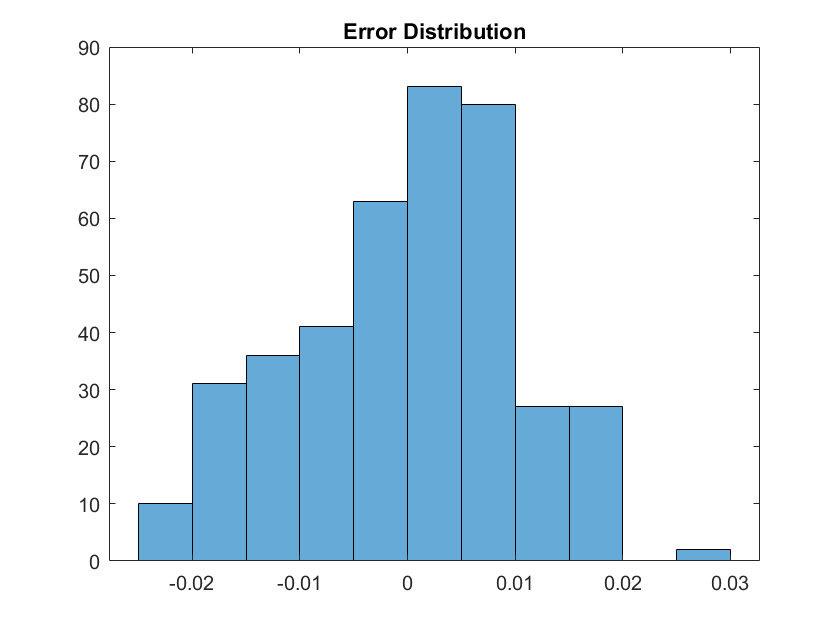

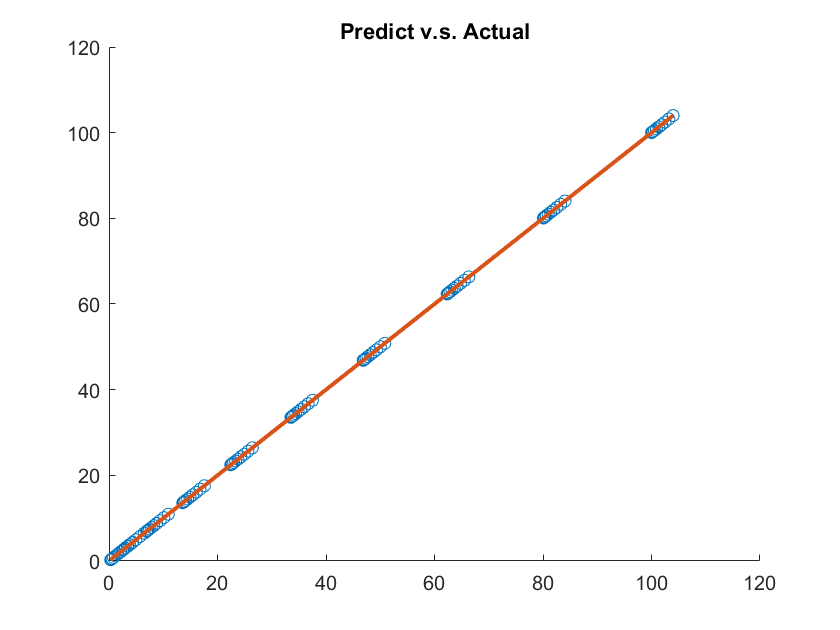

Report=FittingReport(data,label,NN);

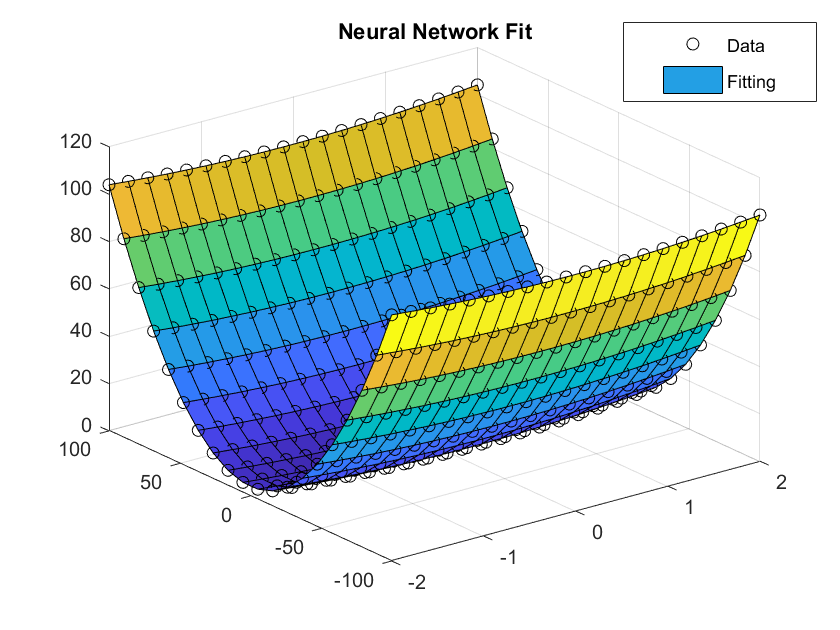


prediction=NN.Evaluate(data);
figure
scatter3(data(1,:),data(2,:),label,'black')
hold on
[X,Y]=meshgrid(x1,x2);
n1=numel(x1); n2=numel(x2);
surf(X,Y,reshape(prediction,n1,n2))
title('Neural Network Fit')
legend('Data','Fitting')
legend("Position", [0.74111,0.83804,0.23204,0.12684])

## 2. Pay Attention to the Scale of Label

If all the label values are very close to the mean value, it can make the neural network difficult to train.

This situation often occurs in physics-related data. Take the following function as an example :

                                        
$$f\left(x\right)=1+0\ldotp 001\sin \left(x\right),x\in \left\lbrack 0,2\pi \;\right\rbrack$$


clear;
n=200;
data=linspace(0,2*pi,n);
label=1+0.001*sin(data);

In such cases, the neural network tends to learn only the mean value of the labels. To address this, a simple solution is to normalize the labels using the following command:

NN.LabelAutoScaling='on';

Set up NN structure and solver

% Define Structure
InputDimension=1; OutputDimension=1;
LayerStruct=[InputDimension,3,4,OutputDimension];
NN=Initialization(LayerStruct,NN);
% Solver Set Up
option.MaxIteration=500;
NN=OptimizationSolver(data,label,NN,option);

Iteration : 6 , Cost :       2.43129868 
Iteration : 12 , Cost :       1.67597631 
Iteration : 18 , Cost :       1.40407791 
Iteration : 24 , Cost :       1.16342545 
Iteration : 30 , Cost :       0.92411354 
Iteration : 36 , Cost :       0.69912992 
Iteration : 42 , Cost :       0.50997694 
Iteration : 48 , Cost :       0.36724800 
Iteration : 54 , Cost :       0.27081727 
Iteration : 60 , Cost :       0.20979860 
Iteration : 66 , Cost :       0.17012450 
Iteration : 72 , Cost :       0.14229122 
Iteration : 78 , Cost :       0.12088135 
Iteration : 84 , Cost :       0.10276357 
Iteration : 90 , Cost :       0.08829856 
Iteration : 96 , Cost :       0.07668985 
Iteration : 102 , Cost :       0.06777021 
Iteration : 108 , Cost :       0.06054833 
Iteration : 114 , Cost :       0.05404448 
Iteration : 120 , Cost :       0.04881848 
------------------------------------------------------
First Stage Optimization Finished in  125  Iteration.
------------------------------------------------

Visualize & Quatify Fitting Performance

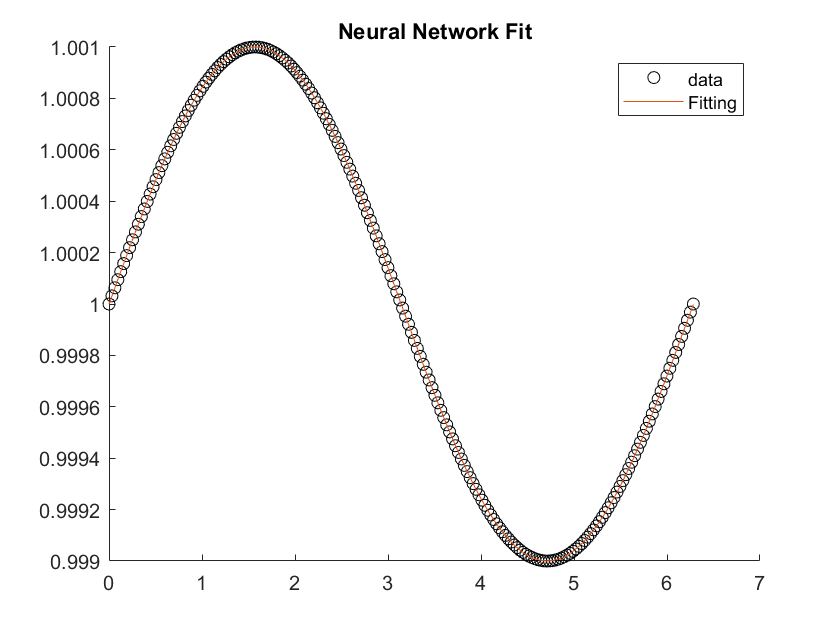

prediction=NN.Evaluate(data);
figure
scatter(data,label,'black')
hold on
plot(data,prediction)
title('Neural Network Fit')
legend('data','Fitting')

Finally, after applying `NN.InputAutoScaling` or `NN.LabelAutoScaling`, the `NN.Evaluate` function 

will also consider the autoscaling. Therefore, **when using the trained neural network**

** for evaluation, there is no need to revert the data or labels to their original scale. **

**You can directly use the original data with the **`NN.Evaluate`** function to obtain results in the correct scale.**

## **3. Training Deep Neural Networks**

If you have a complex problem that requires a deeper neural network to learn effectively, 

it is recommended to use `'``ResNet'`. This type of neural network addresses the issue of 

vanishing gradients, making it possible to train very deep neural nets.